# Substitution Practice

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

A thorough understanding of the integral as an antiderivative can only take you so far. Just as with derivatives, there are integration rules that can be built through the combination of functions as well. The method of substitution that will be discussed in this live script applies to nearly every integral you will ever calculate. In fact, you will likely forget that you are even applying it in some cases because it will become so natural to use!

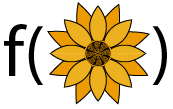

The method of substitution allows you to replace a complicated integral with a simpler one.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

clear gPrime uPrime NewMeasure Measure g fa fb fc fu f MyFun MyAnswer LastFive
 

## **Practice using substitution**

Rewrite each of the following integrals in terms of the new variable provided by the substitution function,$\displaystyle \int f(g(x))g'(x)dx = \int f'(g)\; dg.$. Then solve the integral.

### **Exercise 1**

$\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

First, find the derivative of $g(x)$ with respect to $x$:

gPrime = @(x) x;

What is the new measure $dg$ going to be in terms of $x$ and $dx$?

NewMeasure = @(x,dx)dx;

If we define $\displaystyle \int 15\sin(3x^5)x^4\; dx = \int f(g)\; dg$, what is $f(g)$?

fa = @(g) g;

Calculate the function $F(x) = \displaystyle \int 15\sin(3x^5)x^4\; dx$.

Answer = @(x,C) x;
Check1a(gPrime,fa,NewMeasure,Answer);
 

  **Note: **In many textbooks it is common to use a variable $u$ in place of the variable $g$ or even to call this method $u$-substitution. 

### Exercise 2

$\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$ 

Calculate the derivative $u'(t)$.

uPrime = @(t) t;

Calculate the new bounds and new measure for the integral in terms of $u$. 

ua = 1;
gb = 3;
NewMeasure = @(t,dt)dt;

If we define $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt = \int_{u(a)}^{u(b)} f(u)\cdot du$, what is $f(u)$?

f = @(u)u;

Calculate the function $F(t) = \displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$.

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("This is a definite integral. Your solution should be a number.")
    else
        rethrow(ME)
    end
end
Check1b(uPrime,f,ua,gb,NewMeasure,Answer);
 

### **Exercise 3**

$\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

Remember that $e^x$ is written as `exp(x)` in MATLAB.

gPrime = @(r) r;
NewMeasure = @(r,dr)dr;

If we define $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ $= \int f(q)\cdot \; dq$,

fc = @(q) q;
Answer = @(r,C) r;
Check1c(gPrime,fc,NewMeasure,Answer);
 

### **Exercise 4**

$\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

gPrime = @(w) w;
ga = -1;
gb = 2;
measure = @(w,dw)dw;

Remember that $\ln(g)$ is written `log(g)` in MATLAB.

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{g(a)}^{g(b)}f(g)\cdot dg,$

fb = @(g) g;

This result is still not immediately computable, so let's make another substitution with $u(g) = \ln(g)$. 

If we define $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ $= \displaystyle \int_{u(a)}^{u(b)}f(u)\cdot du,$

ua = -1;
ub = 2;

Calculating $du$ as a function of $g$:

nextMeasure = @(g,dg)dg;
fu = @(u) u;

Putting everything together, compute the result:

try
    Answer =  0;
catch ME
    if contains(ME.message,"Unrecognized function or variable")
        Answer = 0;
        warning("This is a definite integral. Your solution should be a number.")
    else
        rethrow(ME)
    end
end
Check1d(gPrime,fb,ga,gb,measure,nextMeasure,ua,ub,fu,Answer);
 

## Practice Randomized Substitution Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear ErrorCount TotSubProbs TotAttempts adjustcount LastFive MyFun VarChoice
syms t r x z C              % Declare symbolic variables
VarOpts = [t r x z];        % Define the list of variables to use in the problems
ErrorCount = 0;             % Initialize a count of errors
TotSubProbs = 0;            % Initialize a count of total problems attempted
TotAttempts = 0;            % Initialize a count of total solutions offered
AdjustCount = 0;            % Preserve the counts if the user resubmits a solution
LastFive = zeros(1,5);      % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Substitution Practice.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("TotSubProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [MyFun,VarChoice] = GenProbType(VarOpts,1);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    TotSubProbs = TotSubProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

MyAnswer = r;     % User-defined solution, default value r
TotAttempts = TotAttempts + 1;       % Updates count of total attempts at solution
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotSubProbs, ...
    AdjustCount,MyFun,VarChoice,MyAnswer,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
AnalyzeResults(TotSubProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Substitution" in the Integrals section. The app will open in a new window.

[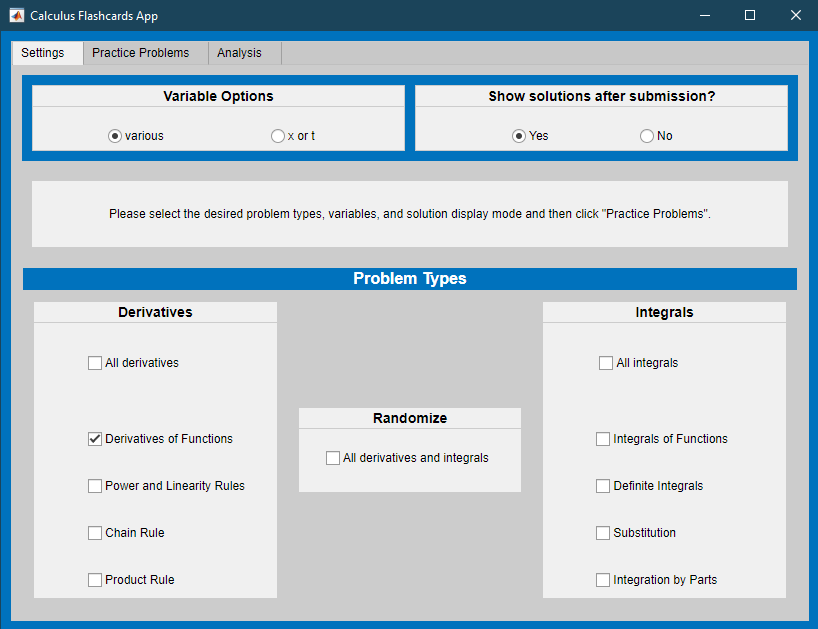](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

% % Practice Problem Generating Functions

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% AnalyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% Check1 generates correct answers by differentiating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = int(myFunc,myVar)+C;
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
switch probType
    case 1 % Simple derivative
        syms f(x) g(x) x
        [f(x),prevFuncType] = GenFunDiff([1 3],x,[1 10],0);
        g(x) = GenFunDiff([1 5],x,[5 10],prevFuncType);
        myFun = diff(f(g(varChoice)),varChoice);
        % Display the integral problem
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice)")
end
end

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t+d);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t+d);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t+d);
    case 10
        f(t) = a*cos(b*t+d);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t+d);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t+d);
end
myFunc = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
            [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

**Exercise 1 Solutions**

a. $\displaystyle \int 15\sin(3x^5)x^4\; dx$ where $g(x) = 3x^5$

function Check1a(gp,fsub,newMeasure,soln)
syms C x g dx dg %#ok<NASGU>
fg = @(g) sin(g);
gpans = @(x) diff(3*x^5,x);
measAns(x,dx) = gpans*dx;
correctAns = @(x,C)int(15*sin(3*x^5)*x^4,x)+C;
if isequal(gp(x),x) && isequal(fsub(g),g) && isequal(newMeasure(x,dx),dx) && isequal(soln(x,C),x)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(x,dx) == measAns(x,dx),"Unknown","false");
    a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    if a1
        displayFormula(['"Correct.  "' "dg/dx = gpans"])
    else
        disp("You do not have the correct function for g'(x).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(15*sin(3*x^5)*x^4,x) = correctAns"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

b. $\displaystyle \int_1^3 \left(\frac{1+t}{t^2+5}\right)^{2/3}\left(\frac{5-2t-t^2}{(t^2+5)^2}\right)\; dt$ where $u(t) = \frac{1+t}{t^2+5}$

function Check1b(gp,fsub,ua,ub,newMeasure,soln)
syms t u du dt a b %#ok<NASGU>
ut = @(t) (1+t)/(t^2+5);
fg = @(u) u^(2/3);
gpans = @(t) diff((1+t)/(t^2+5),t);
uaVal = ut(1);
ubVal = ut(3);
measAns = @(t,dt) gpans*dt;
correctAns = int(((1+t)/(t^2+5))^(2/3)*(5-2*t-t^2)/(t^2+5)^2,t,[1 3]);
if isequal(gp(t),t) && isequal(fsub(u),u) && ua == 1 && ub == 3 && isequal(newMeasure(t,dt),dt) && soln == 0
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isAlways(fg(t)==fsub(t),"Unknown","false");
    a5 = uaVal == ua;
    a6 = ubVal == ub;
    a3 = isAlways(newMeasure(t,dt) == measAns(t,dt),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    if a1
        displayFormula(['"Correct.  "' "du/dt = gpans"])
    else
        disp("You do not have the correct function for u'(t).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "du = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(u) = fg"])
    else
        disp("You do not have the correct function for f(u)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the integral: "' "u(a) = ua" '" and "' "u(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound.")
    end
    if a4
        decimalAns = vpa(correctAns); %#ok<NASGU>
        displayFormula(['"Correct, the value of this integral is "' "correctAns = decimalAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4 ~a5 ~a6])
        disp("Please try again.")
    end
end
end

c $\displaystyle \int e^{r}\cos\left(e^r-17\right)\; dr$ where $q(r) = e^r-17$ 

function Check1c(gp,fsub,newMeasure,soln)
syms C x r q dq dr %#ok<NASGU>
fg = @(q) cos(q);
gpans = @(r) diff(exp(r)-17,r);
measAns = @(r,dr)gpans*dr;
correctAns = @(r,C)int(exp(r)*cos(exp(r)-17),r)+C;
if isequal(gp(r),r) && isequal(fsub(q),q) && isequal(newMeasure(r,dr),dr) && isequal(soln(r,C),r)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(x)==gpans(x),"Unknown","false");
    a2 = isAlways(fg(x)==fsub(x),"Unknown","false");
    a3 = isAlways(newMeasure(r,dr)==measAns(r,dr),"Unknown","false");
    try
        a4 = isAlways(correctAns(x,C)==soln(x,C),"Unknown","false");
    catch ME
        a4 = false;
        if ME.message == "Unrecognized function or variable 'q'."
            a4flag = "q";
        else
            rethrow(ME)
        end
    end
    if a1
        displayFormula(['"Correct.  "' "dq/dr = gpans"])
    else
        disp("You do not have the correct function for q'(r).")
    end
    if a3
        displayFormula(['"Correct. The new measure is "' "dq = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.  "' "f(q) = fg"])
    else
        disp("You do not have the correct function for f(q)")
    end
    if a4
        displayFormula(['"Correct.  "' "int(exp(r)*cos(exp(r)-17),r) = correctAns"])
    elseif exist("a4flag","var") && a4flag == "q"
        displayFormula(['"The solution should be a function of "' "r" '" not "' "q"])
    elseif isAlways(correctAns(x,0)==soln(x,0),"Unknown","false")
        disp("Incorrect. You forgot the +C.")
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~a2 ~a3 ~a4])
        disp("Please try again.")
    end
end
end

d. $\displaystyle \int_{-1}^{2} \left(\ln\left(1+w^2\right)\right)^{7}\left(\frac{w}{1+w^2}\right)\; dw$ where $g(w) = 1+w^2$. 

function Check1d(gp,fgsub,ua,ub,newMeas1,newMeas2,ua2,ub2,fusub,soln)
syms t w g u dg du dw a b %#ok<NASGU>
% First substitution
ut = @(w) 1+w^2;
fg = @(g) (log(g))^7*(0.5/g);
gpans = @(w) diff(1+w^2,w);
gaVal = ut(-1);
gbVal = ut(2);
% Second substitution
uw = @(w) log(1+w^2);
uaVal = uw(-1);
ubVal = uw(2);
fu = @(u) 0.5*u^(7);
measAns = @(w,dw)gpans*dw;
meas2Ans = @(g,dg)diff(log(g),g)*dg;
correctAns = int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2]);
if isequal(gp(w),w) && isequal(fgsub(g),g) && ua == -1 && ub == 2 && isequal(newMeas1(g,dg),dg) && soln == 0 ...
        && isequal(newMeas2(g,dg),dg) && ua2 == -1 && ub2 == 2 && isequal(fusub(u),u)
    disp("Please attempt to solve this problem before submitting.")
else
    a1 = isAlways(gp(t)==gpans(t),"Unknown","false");
    a2 = isequal(fg(t),fgsub(t));
    a5 = gaVal == ua;
    a6 = gbVal == ub;
    a3 = isAlways(newMeas1(w,dw) == measAns(w,dw),"Unknown","false");
    a4 = abs(double(correctAns)-soln)<10*eps;
    a7 = isAlways(newMeas2(g,dg) == meas2Ans(g,dg),"Unknown","false");
    a8 = isequal(fu(t),fusub(t));
    a9 = uaVal == ua2;
    a10 = ubVal == ub2;
    if a1
        displayFormula(['"Correct.  "' "dg/dw = gpans"])
    else
        disp("You do not have the correct function for g'(w).")
    end
    if a3
        displayFormula(['"Correct. The new measure for the first integral is "' "dg = measAns"])
    else
        disp("Incorrect measure.")
    end
    if a2
        displayFormula(['"Correct.   "' "f(g) = fg"])
    else
        disp("You do not have the correct function for f(g)")
    end
    if a5 && a6
        displayFormula(['"You have the correct values for the bounds of the first integral: "' "g(a) = ua" '" and "' "g(b)=ub"])
    elseif ~a5 && ~a6
        disp("You have not calcuated the correct values for the bounds of the first integral.")
    elseif a5
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the first integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the first integral.")
    end
    if a9 && a10
        displayFormula(['"You have the correct values for the bounds of the second integral: "' "u(a) = log(ua)" '" and "' "u(b) = log(ub)"])
    elseif ~a9 && ~a10
        disp("You have not calcuated the correct values for the bounds of the second integral.")
    elseif a9
        disp("You have calcuated the correct lower bound, but not the correct upper bound of the second integral.")
    else
        disp("You have calculated the correct upper bound, but not the correct lower bound of the second integral.")
    end
    if a7 && a8
        displayFormula(['"Correct. The new measure for the second integral is "' "du = measAns";...
            '" and the integrand is "' "f(u) = fu"])
    elseif a7 && ~a8
        disp("Correct measure, but incorrect integrand in the second integral.")
    elseif ~a7 && a8
        disp("Incorrect measure, but correct integrand in the second integral.")
    else
        disp("Incorrect measure and incorrect integrand in the second integral.")
    end
    if a4
        displayFormula(['"Correct, the value of this integral is "' "int((log(1+w^2))^7*(w/(1+w^2)),w,[-1 2])==correctAns"])
    else
        disp("Incorrect final result. Did you use the correct variable?")
    end
    if any([~a1 ~(a2&a3) ~a4 ~a5 ~a6 ~(a7&a8)])
        disp("Please try again.")
    end
end
end